# Edge Detection Example

This example shows the implementation of an edge detector for a image processing pipeline.

## Matlab Implementation

The Matlab implementation uses convolution filters using Sobel Filter values to detect the horizontal and vertical edges.

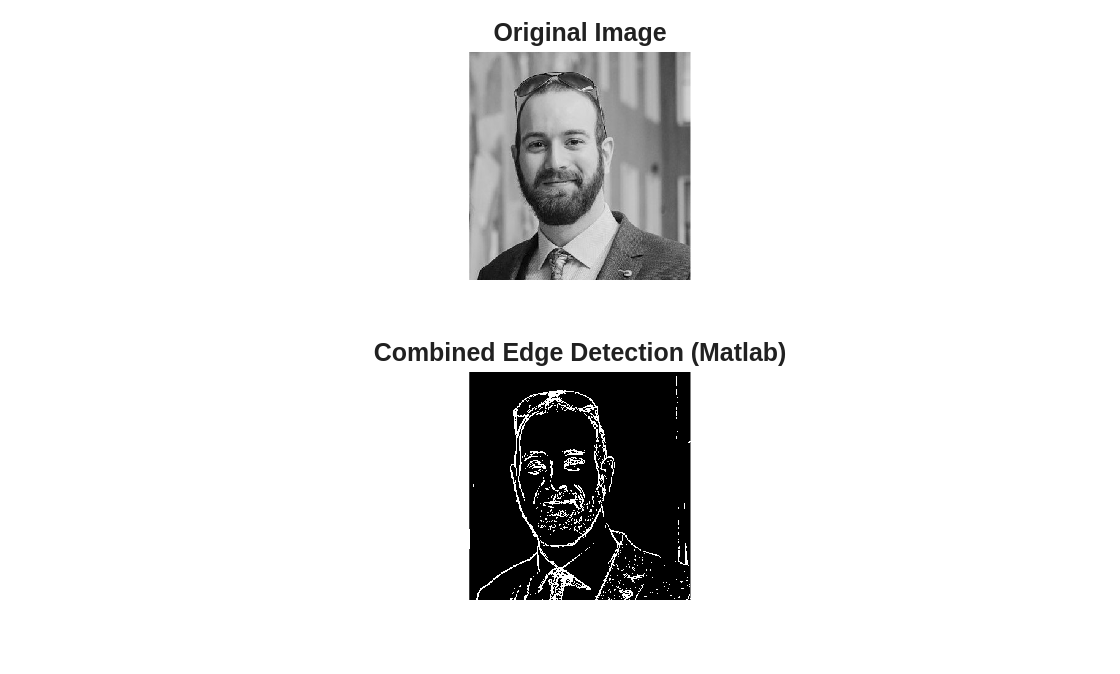

% Read and prepare the image
input_image = imread('adam.jpg');

% Convert to grayscale if needed
if size(input_image, 3) == 3
    input_image_gray = rgb2gray(input_image);
else
    input_image_gray = input_image;
end

% Convert to double for processing
input_image_gray = double(input_image_gray);

% Define Sobel filter kernels
sobel_kx = [-1 0 1; -2 0 2; -1 0 1];  % Horizontal edges
sobel_ky = [-1 -2 -1; 0 0 0; 1 2 1];  % Vertical edges

% Threshold controls the edge sensitivity (0 - 1)
threshold = 0.15;

[edge_bin] = edge_detect(input_image_gray,sobel_kx,sobel_ky,threshold);

% Display results
figure;
subplot(2, 1, 1);
imshow(uint8(input_image_gray));
title('Original Image');

subplot(2, 1, 2);
imshow(edge_bin);
title('Combined Edge Detection (Matlab)');

## Matlab Hardware Implementation

Unfortunately, the above implementation would not be reasonablly realizable on hardware. We need to decide how many pixels to process per cycle cycle and how many cycles we want it to take. None of that information is contained in the high-level implementaton above.

We will implement the edge detector in the following way for hardware:

- Iterate through 3x3 chunks from the input image, working on one 3x3 chunk at a time

- In parellel, we will convolve the x and y kernels with the 3x3 chunk

- A valid output image will be generated once all 3x3 chunks have been created.

% Housekeeping variables
input_image_size = size(input_image_gray);
x_size = input_image_size(1);
y_size = input_image_size(2);

% Process in 3x3 chunks
x_chunk = 3; y_chunk = 3;
current_chunk = zeros(x_chunk,y_chunk);

% Output image is 2 pixels smaller than input image on all sizes due to
% convolution
edge_mag = zeros(x_size-x_chunk+1,y_size-y_chunk+1);

% Process 3x3 chunks
for y_start = 1:y_size-y_chunk+1
    for x_start = 1:x_size-x_chunk+1
        y_end = y_start + y_chunk - 1;
        x_end = x_start + x_chunk - 1;
        current_chunk = input_image_gray(x_start:x_end,y_start:y_end);

        % Perform convolution (product and summation)
        edge_x = sum(sum(current_chunk.*sobel_kx));
        edge_y = sum(sum(current_chunk.*sobel_ky));

        % Combine the gradients to get edge magnitude
        edge_mag(x_start,y_start) = sqrt(edge_x.^2 + edge_y.^2);
    end
end

% Normalize to [0, 1] range
edge_mag = edge_mag / max(edge_mag(:));

% Apply threshold to create binary edge map
edge_bin = edge_mag > threshold;

figure;
imshow(edge_bin);
title('Combined Edge Detection (Matlab HW)');

## Simulink Implementation

We will now convert the Matlab Hardware Implementation to Simulink so we can generate HDL Code